# **An investigation of the quantum mechanical properties of a particles moving through a series of wells**

### **F321911**

In this lab script I am going to be solving a variety of problems involving potential wells inside MATLAB. For the first question I will look at a symmetrical well double well potential. 

### **The symmetric double well problem:**

For this question we must first consider that this system behaves as a 2-dimensional Hilbert space since there are two wells. We can therefore identify that for this Hilbert space there are different states of the system represented through column vectors.


$$\ket{\Psi} '= C_1\ket{\Psi_1} '+ C_2\ket{\Psi_2} $$


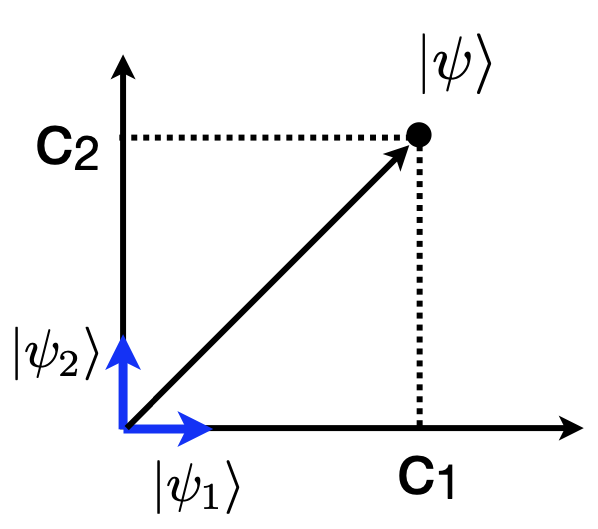

In our first question $\ket{\Psi_1}$ represents the particle in the first well. conversely $\ket{\Psi_2}$ represents the particle being in the second well. It is important to note that these values contribute to a particles that does not have a distinct fixed postition, but that is delocalised and exists within a range of values.

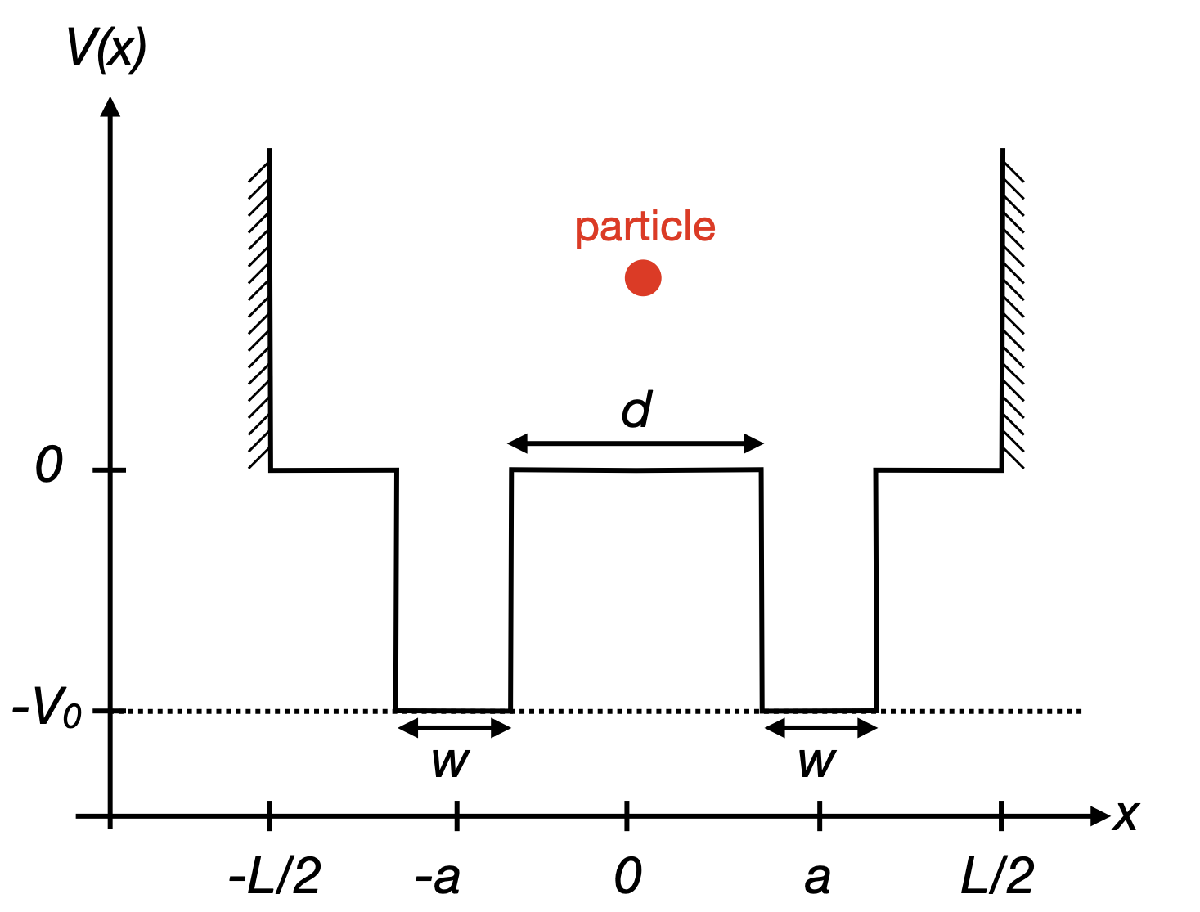

Next, I will consider the Hamiltonian and expectation values. Assuming we know all the information of the system, we can calculate the expectation values of the system of every quantity of the system. For example, for position. 

Matrix representation of postitions:


$$x=   \pmatrix{-a & 0 \cr 0 & a}
$$


Expectation value of X:


$$\bra{\Psi} 'x \ket{\Psi}'= (C_1^* \ C_2^*) \ \pmatrix{-a & 0 \cr 0 & a} \pmatrix{C_1\cr C_2}$$


This simplifies to:


$$-a|c_1|^2 + a|c_2|^2 = P_1(-a) + P_2(a)$$


This therefore means that the probability of the particle being in either of the wells is $P_1$ and $P_2$ respectively. To calculate the different states of the system I am going to use the Hamiltonian since the only possible stationary states are the eigenstates of the Hamiltonian for this system. Since at first we are working with a 2D Hilbert space we will get 2 eigenstates for the system.

The Hamiltonian in this case can be represented as.


$$H =   \pmatrix{H_{11} & H_{12} \cr H_{21} & H_{22}} = \pmatrix{\epsilon_1 & t \cr t^* & \epsilon_2}
$$


Where $\epsilon_1 $ and $\epsilon_2 $ are the expectation values of the particle in $\Psi_1$ and $\Psi_2$. Since in this first problem the wells are identical these values will be the same, these values are representing the potential of each well. The value of t is amplitude to tunnel between the two wells where $t^*$ is the complex conjugate of $t$ and they are numbers that depend on the distance between the two wells.

To start Question 1, we are asked us to start by writing a programme to calculates the eigenvalues and eigenvectors of H for any choice of t. 

We are also told that:


$$H =    \pmatrix{-1 & t \cr t^*& -1}, \  x =    \pmatrix{-1 & 0 \cr 0& 1}$$


This will involve creating variables for the Hamiltonian and the value of t. It will also require the use of two function to find both the eigenvalues and eigenvectors for a given t. First though I will consider how this problem is solved analytically, for example first taking t to be equal to 0.5.


$$H =    \pmatrix{-1 & 0.5 \cr 0.5& -1}$$


The eigen values that are associated with this matrix are:


$$\lambda _1 = \frac{-3}2,\ \lambda _2 = \frac{-1}2$$


Therefore we can calculate that the eigenvectors for these eigenvalues of this system are:


$$\lambda _1 = \frac{-3}2 , v_1= \pmatrix{-1 \cr 1} 
$$
 
$$\lambda _2 = \frac{-1}2 , v_1= \pmatrix{1 \cr 1} 
$$



$$v_1= \frac{1}{\sqrt2} \pmatrix{-1 \cr 1}  = \pmatrix{-\frac{1}{\sqrt2} \cr \frac{1}{\sqrt2}} $$
 
$$v_2= \frac{1}{\sqrt2} \pmatrix{1 \cr 1}  = \pmatrix{\frac{1}{\sqrt2} \cr \frac{1}{\sqrt2}} $$


If we then consider the first eigenstate case:


$$\ket{\Psi} '= C_1\ket{\Psi_1} '+ C_2\ket{\Psi_2}  '= \pmatrix{C_1 \cr C_2 }_{\ket{\Psi_1}',\ket{\Psi_2}}$$



$$C_1 = \frac{1}{\sqrt2} , C_2 = -\frac{1}{\sqrt2} $$



$$P_1 = \frac{1}{2} , \  P_2 = \frac{1}{2$$


To program this I first start be introducing the variables I described: 

% Question 1.1

% Initial variables
H = [-1 0 ; 0 -1];
tValueQuestion1 = 0.5;

% Calculate Eigenvectors of H
eVectOfMatrix(H,tValueQuestion1)

ans =     0.7071    0.7071
   -0.7071    0.7071



% Calculate EigenValues of H
eValsOfMatrix(H,tValueQuestion1)

ans =    -1.5000
   -0.5000



% Calculate Probabilty of each particle
calculateProbability(eVectOfMatrix(H,tValueQuestion1))

ans =     0.5000    0.5000


We see here that the results of the eigenvector opereration gives a two vectors one which is (0.7071, -0.7071), and (0.7071, 0.7071). This would correspond to a probability of 50% for both wells.

For the next part of the question, we are asked to investigate the evolution of the energy structure as t changes. For this problem we will need to introduce a few new variables: And upper and lower bound for t, a two dimensional array to store the eigen values and two arrays to store the upper and lower values of those eigenvalues. There should be one level crossing from the graph at t = 0. This is because:


$$H =    \pmatrix{-1 & 0 \cr 0& -1}$$



$$\lambda _1 = -1,\ \lambda _2 =-1$$


Since both eigenvalues are the same there will be a level crossing.

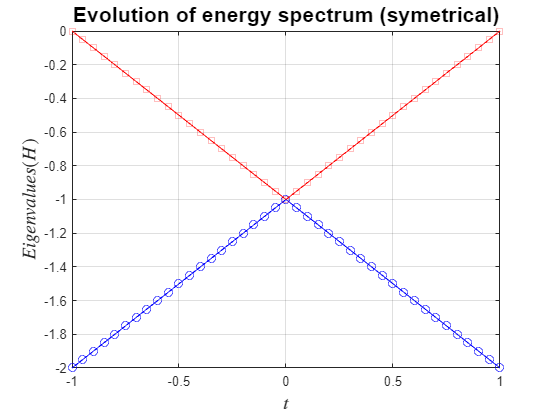

% Question 1.2

EigenvaluesH = [];
stepValue = 20;
tLowerRange = -1;
tUpperRange = 1;

% Loop through t to find values for H
for t = tLowerRange:1/stepValue:tUpperRange

    % Calculate eigenValues of H
    EigenvaluesH = [EigenvaluesH, eValsOfMatrix(H,t);];

    % Seperate the eigenvalues
    topEigenValueH = EigenvaluesH(1, :);
    bottomEigenValueH = EigenvaluesH(2, :);
end

% Plot the eigenvalues against t
x = tLowerRange:1/stepValue:tUpperRange;
figure; hold on;
box on;
grid on;
plot(x,topEigenValueH,'b-o')
plot(x,bottomEigenValueH,'r-s')
title('Evolution of energy spectrum (symetrical)','FontSize',16);
xlabel('$t$','interpreter','latex','FontSize',14);
ylabel('$Eigenvalues(H)$','interpreter','latex','FontSize',14);

As we can see this graph of the different eigenvalues against t, there is a level crossing at t = 0.

The final part of this question asks us to calculate the expectation values of the operator x at different values of t. Firstly I will start with an analytical approach to this question by considering first t to be 0.5. Recall that the expectation value is calculated by:


$$\bra{\Psi} 'x \ket{\Psi}'= (C_1^* \ C_2^*) \ \pmatrix{-a & 0 \cr 0 & a} \pmatrix{C_1\cr C_2}$$


Where in this question we know the value of a to be equal to 1. We also know from the previous question that $C_1$ and $C_2$ are equal to the two eigenvectors of the hamiltonian at a specfic t. Therefore we can calculate that:


$$\bra{\Psi} 'x \ket{\Psi}'= \pmatrix{\frac{1}{\sqrt2} \ -\frac{1}{\sqrt2}}  \ \pmatrix{-1 & 0 \cr 0 & 1} \ \pmatrix{\frac{1}{\sqrt2} \cr -\frac{1}{\sqrt2}} $$


This simplifes to:


$$\bra{\Psi} 'x \ket{\Psi}'= -\pmatrix{\frac{1}{\sqrt2} }^2  +\ \pmatrix{\frac{1}{\sqrt2}} ^2$$



$$\bra{\Psi} 'x \ket{\Psi}'= -\frac12  +\frac12 = 0$$


Therefore, we can see that the expectation value at t = 0.5 is 0. This makes sense as the expectation value is just the average of the particle’s location and since it as likely to be in one well as the other the average is 0. It is important to mention that in this case both eigenstates give us the same expectation value of 0. To program this I am going to need to introduce a new function to calculate the expectation value of an operator given two eigenstates. I will also need new variables that store the operator x and two arrays for both expectation values.

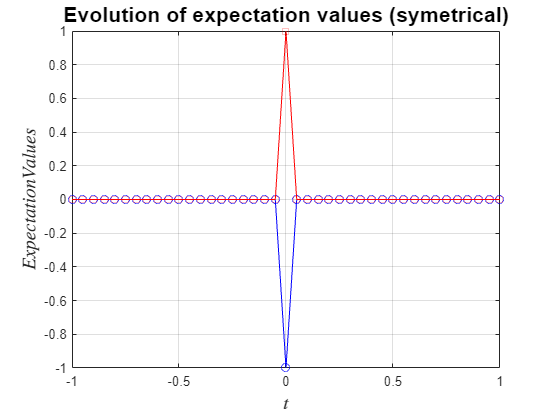

% Question 1.3

X = [-1 0; 0 1];
expectationValues = [];
expectationValues2 = [];


% Loop through t to find values for H
for t = tLowerRange:1/stepValue:tUpperRange

    % Find expectation values of x
    expectationValues = [expectationValues, expecationValues(X,H,t);];
    
    % Find second set of expectation values of x
    expectationValues2 = [expectationValues2, expecationValues2(X,H,t);];
end

% Plot the expectation values of
x = tLowerRange:1/stepValue:tUpperRange;
figure; hold on;
box on;
grid on;
plot(x,expectationValues,'b-o');
plot(x,expectationValues2, 'r-s');
title('Evolution of expectation values (symetrical)','FontSize',16);
xlabel('$t$','interpreter','latex','FontSize',14);
ylabel('$Expectation Values$','interpreter','latex','FontSize',14);

As we can see the graph shows that at all values of t the expectation value is always 0, however at t = 0 we see degenerate expectation values since the two states refer to the same eigenvalue. For example:


$$\lambda _1 = -1,\ \lambda _2 =-1$$


You may also notice that this t value also lines up with the level crossing from the previous part.

### **The Asymmetric double well problem:**

For the next question we will consider an asymmetrical well in 2D Hilbert space. The well potentials in this case are now -1 and -0.5.

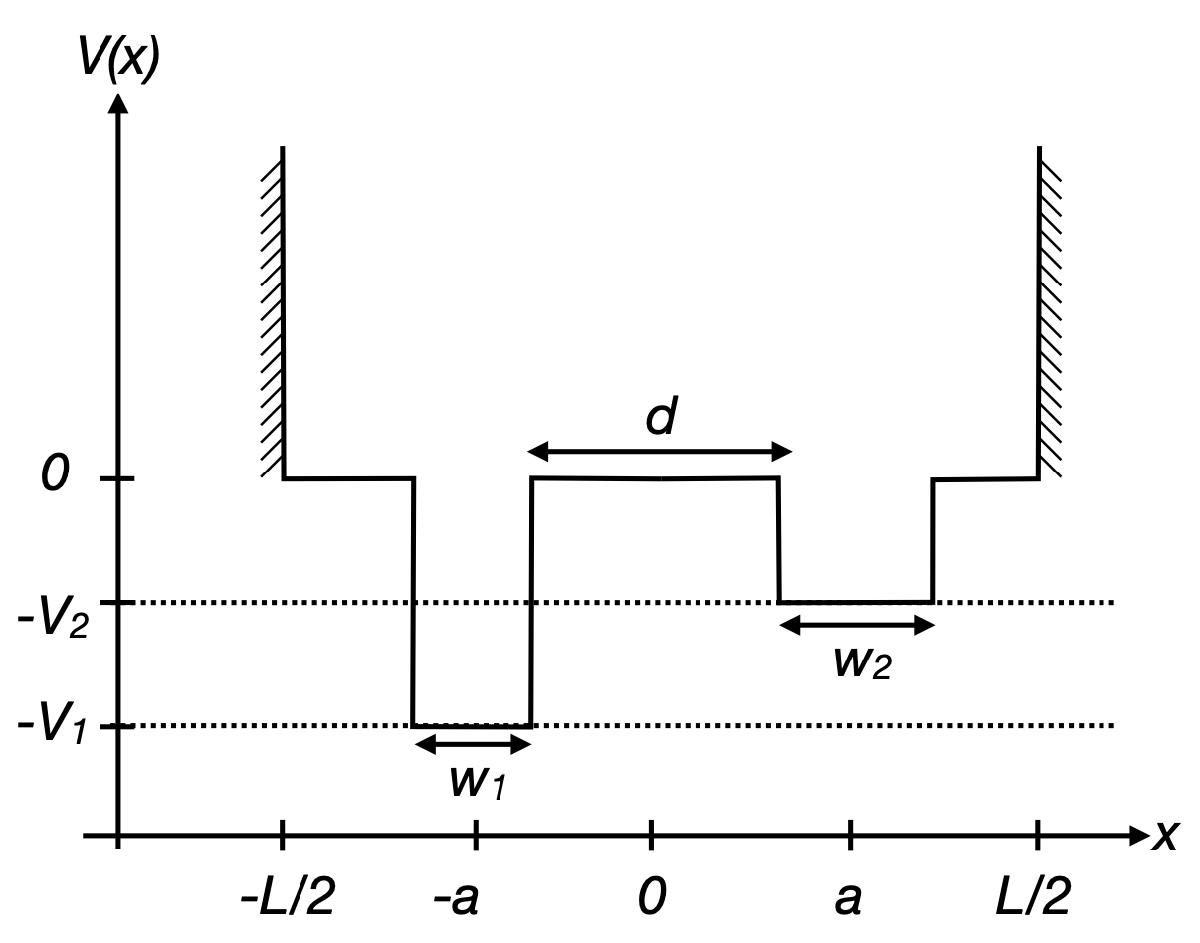

For this question we will need to adjust the Hamiltonian to consider the different value for potential for the second well.


$$H =    \pmatrix{-1 & t \cr t^*& -0.5}$$


Similar to question one I am first going to consider a fixed value such as 0.5 and calculate the eigenstates, eigenvalues and probabilities. For t = 0.5:

    
$$H =    \pmatrix{-1 & 0.5 \cr 0.5& -0.5}$$



$$\lambda _1 = -1.309 , v_1= \pmatrix{-0.851 \cr 0.526} 
$$
 
$$\lambda _2 = -0.191 , v_2= \pmatrix{-0.526 \cr -0.851 } 
$$


For the probabilities considering the first eigenstate we get:


$$\ket{\Psi} '= C_1\ket{\Psi_1} '+ C_2\ket{\Psi_2}  '= \pmatrix{C_1 \cr C_2 }_{\ket{\Psi_1}',\ket{\Psi_2}}$$



$$C_1 = -0.851 , C_2 = 0.526$$



$$P_1 = 0.724 , \  P_2 = 0.276$$


As we can see the sum of the probabilties is still equal to 1. For the first part of the question I will need to change the value of the Hamiltonian matrix to change the potetial of one of the wells.

clear;
% Question 2.1

H = [-1 0 ; 0 -0.5];
tValueQuestion2 = 0.5;

% Calculate Eigenvectors of H
eVectOfMatrix(H,tValueQuestion2)

ans =    -0.8507   -0.5257
    0.5257   -0.8507



% Calculate EigenValues of H
eValsOfMatrix(H,tValueQuestion2)

ans =    -1.3090
   -0.1910



% Calculate Probabilty of each particle
calculateProbability(eVectOfMatrix(H,tValueQuestion2))

ans =     0.7236    0.2764


As we can see the values match to the calculated ones. 

The next question we need to investigate the evolution of the energy spectrum for this system given a change in t. If we consider that the system before had a level crossing at t = 0. We can check if the system has one there too:


$$H =    \pmatrix{-1 & 0 \cr 0& -0.5}$$



$$\lambda _1 = -1,\ \lambda _2 =-0.5$$


Since one of the values is at -0.5 and one is at -1 there should be a gap separating the two graphs.

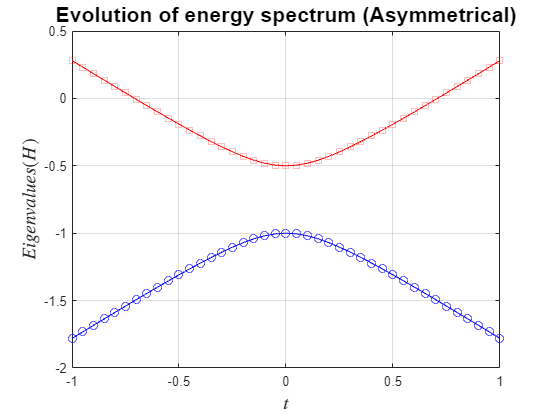

% Question 2.2

EigenvaluesH = [];
stepValue = 20;
tLowerRange = -1;
tUpperRange = 1;


% Loop through t to find values for H
for t = tLowerRange:1/stepValue:tUpperRange
    
    % Calculate EigenValues of H
    EigenvaluesH = [EigenvaluesH, eValsOfMatrix(H,t);];
    
    % Seperate the eigenvalues
    topEigenValueH = EigenvaluesH(1, :);
    bottomEigenValueH = EigenvaluesH(2, :);
end


% Plot for Hamiltonian eigen values against t

figure; hold on;
box on;
grid on;
x=(tLowerRange:1/stepValue:tUpperRange)';
plot(x,topEigenValueH,'b-o')
plot(x,bottomEigenValueH,'r-s')
title('Evolution of energy spectrum (Asymmetrical)','FontSize',16);
xlabel('$t$','interpreter','latex','FontSize',14);
ylabel('$Eigenvalues(H)$','interpreter','latex','FontSize',14);

As we can see from this result there is no longer a level crossing since there is not a value of t where the eigenvalues are the same.

As with the last question the last part of this question is to investigate the evolution of the expectation values of the operator x. I will start this question by first looking at how the expectation values change as t varies. For the symmetrical well all the values were 0 since the wells had the same potential, however this time the two eigenstates will diverge. I will use one example of t to investigate how the expectation values changes. Let’s consider the value of t to be 0.5.

For both values I will be considering the equation previously used:

$\bra{\Psi} 'x \ket{\Psi}'= (C_1^* \ C_2^*) \ \pmatrix{-a & 0 \cr 0 & a} \pmatrix{C_1\cr C_2}$e

For t = 0.5:


$$\bra{\Psi} 'x \ket{\Psi}'= -(0.851)^2 + (0.526)^2$$



$$\bra{\Psi} 'x \ket{\Psi}'\approx -0.448$$


For the second eigenstate:


$$\bra{\Psi} 'x \ket{\Psi}'=  -(0.526)^2 +(0.851)^2 $$



$$\bra{\Psi} 'x \ket{\Psi}' \approx 0.448$$


As we can see the two expectation values are similar however, they negative opposite values of each other. As the value of t tends towards 0 the expectation values get closer to 1 and -1. As the value of t tends away from 0 the expectation values get further from 1 and -1. For example:

For t = 0.4

$\bra{\Psi} 'x \ket{\Psi}' \approx -0.530$, $\bra{\Psi} 'x \ket{\Psi}' \approx 0.530$

For t = 0.6

$\bra{\Psi} 'x \ket{\Psi}' \approx -0.384$, $\bra{\Psi} 'x \ket{\Psi}' \approx 0.384$

These values should therefore produce two graphs that are a bell curve like shape mirrored about the x axis.

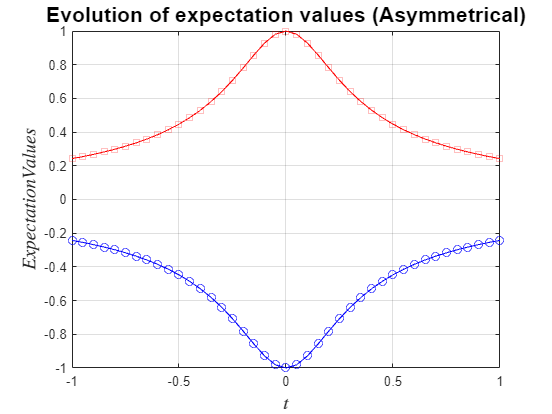

% Question 2.3

X = [-1 0; 0 1];
expectationValues = [];
expectationValues2 = [];

for t = tLowerRange:1/stepValue:tUpperRange

    % Find first set of expectation values of x
    expectationValues = [expectationValues, expecationValues(X,H,t);];
    
    % Find second set of expectation values of x
    expectationValues2 = [expectationValues2, expecationValues2(X,H,t);];

end


figure; hold on;
box on;
grid on;
plot(x,expectationValues,'b-o')
plot(x,expectationValues2,'r-s')
title('Evolution of expectation values (Asymmetrical)','FontSize',16);
xlabel('$t$','interpreter','latex','FontSize',14);
ylabel('$Expectation Values$','interpreter','latex','FontSize',14);

As we see from the graph the expectation values do indeed tend towards 1 and -1 as t approaches 0 and diminishes as t tends away from 0. The two eigen states also diverge from each other showing that the ground state corresponds to the deeper well while the higher state corresponds to the shallower well. At t = 0 the amplitude to tunnel between wells is 0. Therefore, the particle is in either well but not tunnelling between them.

### Extensions:

The next tasks are extensions to previous questions. The first extension to consider is to transform the current program so that it works for any number of wells not just 2.

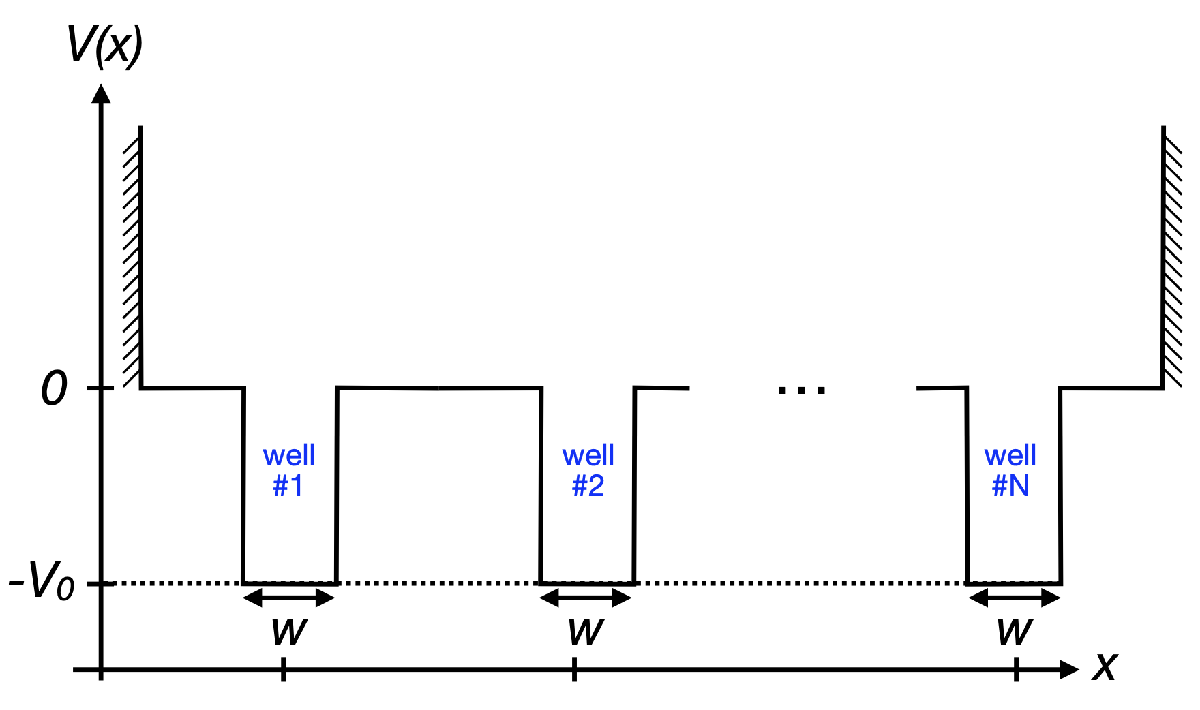

For this to be achieved I will need to change a couple features of the code. Firstly, I will need to change the current functions to make them generic for higher numbers of wells. To do this I will need to introduce a new constant numOfWells to define how many wells are involved in the question, this will be equal to the number of elements in the Hamiltonian array. I will also change the x matrix so that it to can be changed to easily adopt a larger number of wells. Then I will also need to consider how I will find the ground state of the system. In this case I will pass the generic eigenvalues function for the min function and return the index in which the ground state is found. Next, I will also need to reconsider how I’m going to change the functions. For each function I will need to adapt it so that it would work with more than two well. Each of the generic functions have comments explaining how they differ (see below comment % GENERIC functions below: ). 

In addition to this I will need to change the main for loop since I will have new functions. For the graphs I will need to change how I approach the evolution of the energy diagram since I will be plotting an unknown number of graphs. For the ground state graph that will be more straightforward since it is only one graph. Since the code will be working with large matrices it is important to make sure that I keep the code clean and optimised to make sure it can run as efficiently as possible. This included not introducing any unnecessary variables where possible to save memory. I decided to use an array to store the optional geometries of the system since in the future if I wish to expand this beyond these requirements it would be easily scalable.

Now given the changes let’s consider a system of 4 wells. Where the Hamiltonian is equal to:

$H =    \pmatrix{-1 & t & 0 & 0 \cr t^*& -1 & t& 0\cr 0&t^* & -1& t\cr 0& 0& t^*& -1}$ and $x =    \pmatrix{0& 0 & 0 & 0 \cr 0& 1 & 0& 0\cr 0&0& 2& 0\cr 0& 0& 0& 3}$

Given these conditions we should expect the ground state of the particle to be localised around position -0.5 at t = 0 since at this position it is the lowest energy value of the Hamiltonian.

Part 2 of the extensions asks us to add capability to specify ring geometry for the wells, that is where the final well is connected to the first well. To do this I will need to add a feature to the both the generic eigenvalues and eigenvectors code to add the option to choose to use a ring geometry, and also a variable to add the option to choose the ring geometry. Logically all that changes is that the two corner matrix values (that is n, 1 and 1, n) where n is the size of the matrix are now t. For example, considering our previous example. The Hamiltonian now equals:


$$H =    \pmatrix{-1 & t & 0 & t \cr t^*& -1 & t& 0\cr 0&t^* & -1& t\cr t^*& 0& t^*& -1}$$


Part 3 asks us to consider other types of geometries, one configuration i’ve chosen to consider is how what happens when all the wells are connected to each other. To do this I will need to change the Hamiltonian so that all the values other than the expectation value is the value t. For example, in our first case the Hamiltonian would be:


$$H =    \pmatrix{-1 & t & t & t \cr t^*& -1 & t& t\cr t^*&t^* & -1& t\cr t^*& t^*& t^*& -1}$$


A second configuration ive chosen to consider is a 2d grid chain. The hamiltonian for this for 6 wells would look like:


$$H =    \pmatrix{-1 & t & 0 & t & 0 & 0 \cr t^*& -1 & t& 0 & 0 & 0\cr 0&t^* & -1& t & 0 & t\cr t^*& 0& t^*& -1 & t & 0\cr 0& 0& 0& t^* & -1 & t\cr 0& 0& t^*& 0 & t^* & -1}$$


% Extension questions
clear;

% extensionSituations is an array of either 0, 1 representing a certain
% geometry configuration being selected (Not used in this part of the
% extension questions.
extensionSituations = [0,0,0];

% Declare contents of hamiltonian and calculate number of rows and columns
HDiagOfValues = [-1,-0.5,-1,-0.5];
numRowsColumns = numel(HDiagOfValues);

H = diag(HDiagOfValues);
X = diag(0:1:numRowsColumns-1); % Creates postitions from 0 to the number of wells
groundState = [];
eigenValues = [];
stepValue = 20;
tLowerRange = -1;
tUpperRange = 1;
tValueQuestion1 = 0; % Used for first part

% Calculate EigenVectors of H
GENERICeVectOfMatrix(H,tValueQuestion1, numRowsColumns, extensionSituations)

ans =      1     0     0     0
     0     0     1     0
     0     1     0     0
     0     0     0     1




% Calculate EigenValues of H
GENERICeValsOfMatrix(H,tValueQuestion1, numRowsColumns, extensionSituations)

ans =    -1.0000
   -1.0000
   -0.5000
   -0.5000


% Calculate probabilty of different eigenstates
GENERICcalculateProbability(GENERICeVectOfMatrix(H,tValueQuestion1, numRowsColumns, extensionSituations),numRowsColumns)

ans = 1

ans =      1     0     0     0


% Calculate ground state and find the corrosponding index
[groundEnergy, index] = min(GENERICeValsOfMatrix(H,tValueQuestion1, numRowsColumns, extensionSituations))

groundEnergy = -1

index = 1

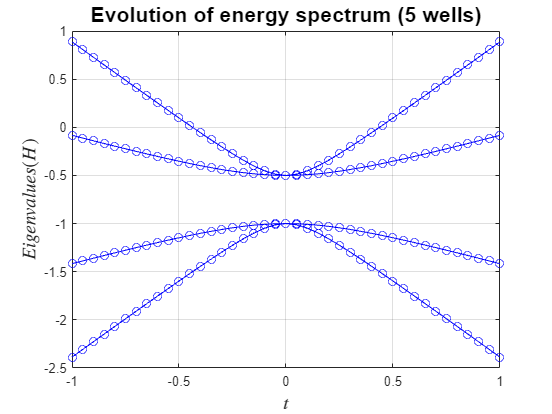


% Loop through t to find values for the eigenvalues and ground state
for t = tLowerRange:1/stepValue:tUpperRange
    eigenValues = [eigenValues, GENERICeValsOfMatrix(H,t,numRowsColumns, extensionSituations)];
    groundState = [groundState, GENERICgroundState(X,H,t,numRowsColumns, extensionSituations, index)];
end

%Loop through each possible eigenvalue and plot it on one graph
figure; hold on;
for i=1:1:numRowsColumns
        box on;
        grid on;
        x=(tLowerRange:1/stepValue:tUpperRange)';
        plot(x,eigenValues(i,:),'b-o');
        title('Evolution of energy spectrum (5 wells)','FontSize',16);
        xlabel('$t$','interpreter','latex','FontSize',14);
        ylabel('$Eigenvalues(H)$','interpreter','latex','FontSize',14);
end

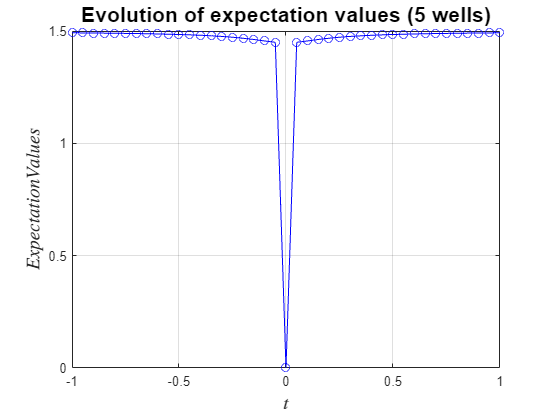

figure; hold on;
box on;
grid on;
x=(tLowerRange:1/stepValue:tUpperRange)';
plot(x,groundState,'b-o');
title('Evolution of expectation values (5 wells)','FontSize',16);
xlabel('$t$','interpreter','latex','FontSize',14);
ylabel('$ExpectationValues$','interpreter','latex','FontSize',14);

function eVect = eVectOfMatrix(H,t)
    % Takes the hamiltonian and adjusts it for t, then calculates
    % eigenvectors.
    H(1,2)=t;
    H(2,1)=t;

    [V,~] = eig(H);
    eVect = V;
end

function eVals = eValsOfMatrix(H,t)
    % Takes the hamiltonian and adjusts it for t, then calculates
    % eigenvalues.
    H(1,2)=t;
    H(2,1)=t;

    eVals = eig(H);
end

function prob = calculateProbability(eVect)
    % Creates an empty array to store results of the probability then
    % squares the values of the first eigenvector
    prob = [];
    prob1 = eVect(1,1)^2;
    prob2 = eVect(1,2)^2;
    prob = [prob1, prob2];

end

function expectValue = expecationValues(X,H,t)  
    % Finds the values of the eigenvector of a given t, then splits it into
    % the first set of eigenvectors
    vect = (eVectOfMatrix(H,t));
    vect1 = vect(:,1);

    expectValue = (vect1'*X*vect1);
end

function expectValue = expecationValues2(X,H,t) 
    % Finds the values of the eigenvector of a given t, then splits it into
    % the second set of eigenvectors
    vect = (eVectOfMatrix(H,t));
    vect2 = vect(:,2);

    expectValue = (vect2'*X*vect2);
end


% GENERIC functions below:

function prob = GENERICcalculateProbability(eVect,numRowsColumns)
    % For each of the number of rows and columns adds the value of the
    % square of the first eigenvector to it therefore returning each of the
    % probabilites in a array
    prob = [];
    for i = 1:1:numRowsColumns
        prob = [prob,eVect(i,1)^2;];
    end
    sum(prob)
end


function modifiedMatrix = GENERICmodifyMatrix(H,t,numRowsColumns,extensionSituations)
    for i = 1:1:numRowsColumns-1        
        H(i,i+1) = t;
        H(i + 1, i) = t;
        if(extensionSituations(1,1) == 1)
            % This is for ring geometry where the final well is connected
            % to the first and vice versa
            H(numRowsColumns, 1) = t;
            H(1, numRowsColumns) = t;
        end
        if(extensionSituations(1,2) == 1)
            % This is for an all connected geometry where the every well is connected
            % every other well
            oppositeMatrix = ~eye(size(H));
            H(oppositeMatrix) = t;
        end
        if(extensionSituations(1,3) == 1)
            % This is for a 2d grid structure
            if(mod(i,2) == 1 && i+3 <= numRowsColumns)
            H(i,i+3) = t;
            H(i+3, i) = t;
            end
        end
    end
    modifiedMatrix = H;
end

function eVals = GENERICeValsOfMatrix(H,t,numRowsColumns,extensionSituations)
    % Takes the amount of rows and columns and changes the off diagonals of
    % the matrix to the value of t then returns the eigenvalues of that new
    % matrix
    H = GENERICmodifyMatrix(H,t,numRowsColumns,extensionSituations);
    eVals = eig(H);
end

function eVect = GENERICeVectOfMatrix(H,t,numRowsColumns,extensionSituations)
    % By default takes the amount of rows and columns and changes the off diagonals of
    % the matrix to the value of t then returns the eigenvectors of that new
    % matrix
    H = GENERICmodifyMatrix(H,t,numRowsColumns,extensionSituations);
    [V,~] = eig(H);
    eVect = V;
end

function groundState = GENERICgroundState(X,H,t,numRowsColumns,finalWellConnection, index)
    % Creates a new vector that takes the value of the eigenvector at value t
    % Then creates an array for the ground states, the ground state is calculated by using the
    % eigenvector that is associated with the groundstate (index). each time the function
    % is called it adds the value of the ground state onto the existing array
    vect = (GENERICeVectOfMatrix(H,t,numRowsColumns,finalWellConnection));
    groundState = [];
    groundState = [groundState, (vect(:,index)'*X*vect(:,index));];
end